%% PROJECT WORK 1- STOCK A6
clear; clc; close all;

csvFile = "btcusd_1-min_data.csv";  
valueCol = "Close";                  
targetPts = 3e4;     

% Load and build timetable
opts = detectImportOptions(csvFile);
T = readtable(csvFile, opts);

% Timestamp -> datetime 
timeRaw = T.Timestamp;
if isnumeric(timeRaw)
    mVal = nanmean(double(timeRaw));
    if mVal > 1e11
        t = datetime(double(timeRaw)/1000, 'ConvertFrom','posixtime', 'TimeZone','UTC');
    else
        t = datetime(double(timeRaw), 'ConvertFrom','posixtime', 'TimeZone','UTC');
    end
else
    t = datetime(string(timeRaw), 'TimeZone','UTC'); 
end

% Select series
assert(ismember(valueCol, string(T.Properties.VariableNames)), ...
    "Column '%s' not found.", valueCol);
y = T.(valueCol);

% cleaned Timetable 
TT = timetable(t, y, 'VariableNames', string(valueCol));
TT = sortrows(TT);
TT = unique(TT);
TT = rmmissing(TT);

fprintf("Observations: %d  |  %s → %s\n", height(TT), datestr(TT.t(1)), datestr(TT.t(end)));

Observations: 7278877  |  01-Jan-2012 10:01:00 → 03-Nov-2025 23:57:00


% continuous measurements with the same frequency?

dt = diff(TT.t);
medStep = median(dt);
isRegular = all(abs(seconds(dt - medStep)) < 1e-9);  

if ~isRegular
    tGrid = (TT.t(1):medStep:TT.t(end)).';
    TTr = retime(TT, tGrid, 'mean');     
else
    TTr = TT;
end

fprintf("Median step: %s | Regular series: %d\n", string(medStep), isRegular);

Median step: 00:01:00 | Regular series: 0



% Missing values
isMiss = ismissing(TTr.(valueCol));
nMiss  = sum(isMiss);
fracMiss = nMiss / height(TTr) * 100;

fprintf('Missing values in %s: %d (%.4f %%)\n', ...
    valueCol, nMiss, fracMiss);

Missing values in Close: 1160 (0.0159 %)



dMiss    = diff([false; isMiss; false]);
missStart = find(dMiss == 1);
missEnd   = find(dMiss == -1) - 1;
blockLen  = missEnd - missStart + 1;

if ~isempty(blockLen)
    fprintf('Number of missing blocks: %d, max block length: %d\n', ...
        numel(blockLen), max(blockLen));
else
    fprintf('No consecutive missing blocks detected.\n');
end

Number of missing blocks: 1, max block length: 1160



TTr_filled       = TTr;
TTr_filled.(valueCol) = fillmissing(TTr.(valueCol),'linear');


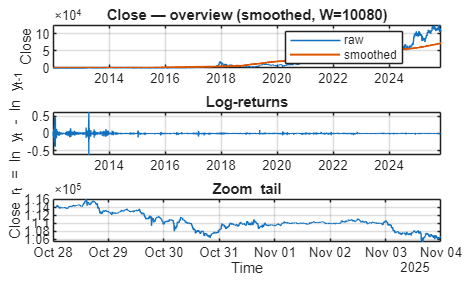

% Visualization

TTp = TTr;
if height(TTp) > targetPts
    k = ceil(height(TTp)/targetPts);
    newT = (TTp.t(1):k*medStep:TTp.t(end)).';
    TTp = retime(TTp, newT, 'mean');
end

figure('Name','Exploratory','Color','w');
tiledlayout(3,1,'Padding','compact','TileSpacing','compact');

nexttile;
plot(TTp.t, TTp.(valueCol), '-', 'LineWidth', 0.6); hold on;
W = max(5, round( seconds(days(7)) / seconds(medStep) )); 
ys = movmean(TTp.(valueCol), W, 'omitnan');
plot(TTp.t, ys, '-', 'LineWidth', 1.2);
grid on; box on;
title(sprintf('%s — overview (smoothed, W=%d)', valueCol, W));
ylabel(valueCol); legend('raw','smoothed','Location','best');

% Log-returns 
nexttile;
r = diff(log(TTr.(valueCol)));
plot(TTr.t(2:end), r, '-'); grid on; box on;
title('Log-returns'); ylabel('r_t = ln y_t - ln y_{t-1}');

% Zoom 
nexttile;
tailN = min(10000, max(1000, round(0.1*height(TTr))));
plot(TTr.t(end-tailN+1:end), TTr.(valueCol)(end-tailN+1:end), '-');
grid on; box on; title(sprintf('Zoom  tail'));
xlabel('Time'); ylabel(valueCol);

% Decomposition + STL outlier detection

TTd = retime(TTr_filled, 'regular', 'mean', 'TimeStep', hours(1));

% consider only last year
tStart = TTd.t(end) - calyears(1);
TTd = TTd(timerange(tStart, TTd.t(end)), :);
Period = 168;

yvec = double(TTd.(valueCol));
yvec = fillmissing(yvec,'linear'); 
yvec = yvec(:);
N = numel(yvec);
Period = max(2, min(Period, floor(N/2)));

% STL decomposition 
[LT, ST, R] = trenddecomp(yvec, "stl", Period);

% outlier
muR = mean(R,'omitnan');
sigR = std(R,[],'omitnan');
zR = (R - muR) / sigR;
thrZ = 3; 
outlierIdx = abs(zR) > thrZ;

fprintf('STL: detected %d outliers in the remainder (|z| > %.1f).\n', ...
    sum(outlierIdx), thrZ);

STL: detected 147 outliers in the remainder (|z| > 3.0).


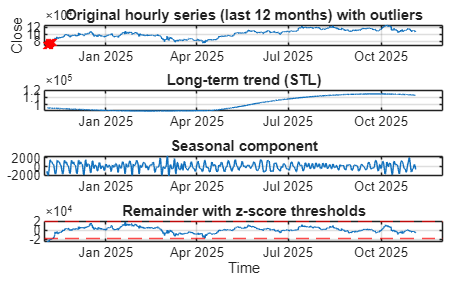


% substitute outlier with trend + seasonal 
yClean = yvec;
yClean(outlierIdx) = LT(outlierIdx) + ST(outlierIdx);

figure('Name','STL decomposition and outliers','Color','w');
tiledlayout(4,1,'Padding','compact','TileSpacing','compact');
nexttile;
plot(TTd.t, yvec, '-'); hold on;
plot(TTd.t(outlierIdx), yvec(outlierIdx), 'rx');
grid on; box on;
title('Original hourly series (last 12 months) with outliers');
ylabel(valueCol);
nexttile;
plot(TTd.t, LT, '-'); grid on; box on;
title('Long-term trend (STL)');
nexttile;
plot(TTd.t, ST, '-'); grid on; box on;
title('Seasonal component');
nexttile;
plot(TTd.t, R, '-'); hold on;
yline( thrZ*sigR + muR, '--r');
yline(-thrZ*sigR + muR, '--r');
grid on; box on;
title('Remainder with z-score thresholds');
xlabel('Time');

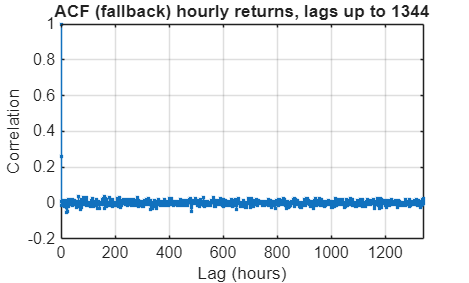

%% ACF
yH = TTd.(valueCol);
yH = fillmissing(yH, 'linear', 'MaxGap', 24, 'EndValues', 'nearest');   
yH = max(yH, eps);                                                     

rH = diff(log(yH));
rH = rH(isfinite(rH));                                              

maxLag = 24*56;                                                      
maxLag = min(maxLag, numel(rH)-1);
if maxLag < 1
    warning('Return serie too short.');
else
    figure('Name','ACF (hourly returns)','Color','w');
    if exist('autocorr','file') == 2
        autocorr(rH, maxLag);
        title(sprintf('ACF of hourly log-returns (NumLags=%d)', maxLag));
        xlabel('Lag (hours)'); ylabel('Autocorrelation');
        grid on;
    else
     
        y0 = rH - mean(rH,'omitnan');
        [c,lags] = xcorr(y0, maxLag, 'coeff');
        keep = lags>=0;
        stem(lags(keep), c(keep), '.'); grid on; box on;
        xlim([0 maxLag]); xlabel('Lag (hours)'); ylabel('Correlation');
        title(sprintf('ACF (fallback) hourly returns, lags up to %d', maxLag));
    end
end

% Partition

TTP = TTd;               
N = height(TTP);
testFrac = 0.20;

cv = tspartition(N, 'Holdout', testFrac);
idxTrain = training(cv);
idxTest = test(cv);

TT_train = TTP(idxTrain,:);
TT_test = TTP(idxTest,:);

fprintf('\n== Holdout (hourly) ==\n');


== Holdout (hourly) ==


fprintf('Train: %d  [%s → %s]\n', height(TT_train), datestr(TT_train.t(1)), datestr(TT_train.t(end)));

Train: 7008  [03-Nov-2024 23:00:00 → 22-Aug-2025 22:00:00]


fprintf('Test : %d  [%s → %s]\n', height(TT_test), datestr(TT_test.t(1)),  datestr(TT_test.t(end)));

Test : 1752  [22-Aug-2025 23:00:00 → 03-Nov-2025 22:00:00]


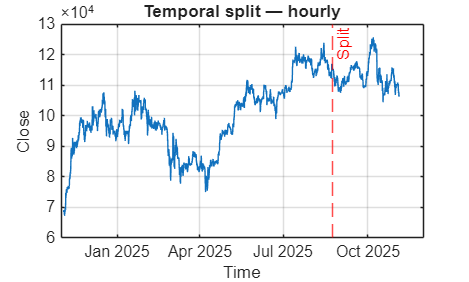


figure('Name','Train/Test Split (hourly)','Color','w');
plot(TTP.t, TTP.(valueCol), '-', 'LineWidth', 0.6); hold on;
xline(TTP.t(find(idxTest,1,'first')-1), '--r', 'Split'); grid on; box on;
title('Temporal split — hourly'); ylabel(valueCol); xlabel('Time');


K = 5;
cvk = tspartition(height(TT_train), "SlidingWindow", K);


% Baseline autoregressive model 

y = TTP.(valueCol);
y = fillmissing(y,'linear');     

noLags = 24;                       
N = numel(y);

Y = y(noLags+1:end);        
nObs = numel(Y);
X = zeros(nObs, noLags);
for i = 1:nObs
    X(i,:) = y(i:i+noLags-1);   
end

idxTrainY = idxTrain(noLags+1:end);
idxTestY  = idxTest(noLags+1:end);

mdl = fitlm(X(idxTrainY,:), Y(idxTrainY));

yhatTrain = predict(mdl, X(idxTrainY,:));
yhatTest  = predict(mdl, X(idxTestY,:));

% metrics
mseTrain = mean((Y(idxTrainY) - yhatTrain).^2);
mseTest  = mean((Y(idxTestY)  - yhatTest ).^2);

maeTrain = mean(abs(Y(idxTrainY) - yhatTrain));
maeTest  = mean(abs(Y(idxTestY)  - yhatTest ));

fprintf('\nAR(%d) baseline on hourly data\n', noLags);


AR(24) baseline on hourly data


fprintf('Train MSE: %.4f | Train MAE: %.4f\n', mseTrain, maeTrain);

Train MSE: 139208.2143 | Train MAE: 248.3442


fprintf('Test  MSE: %.4f | Test  MAE: %.4f\n', mseTest,  maeTest);

Test  MSE: 117039.2741 | Test  MAE: 226.1379


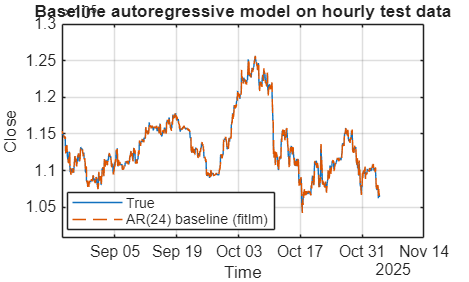


K = 100;  
lastWindow = y(end-noLags+1:end);
yForecast = zeros(K,1);

for k = 1:K
    yForecast(k) = predict(mdl, lastWindow(:)');
    lastWindow   = [lastWindow(2:end); yForecast(k)];
end

figure('Name','AR baseline vs true (test set)','Color','w');
tAll = TTP.t(noLags+1:end);
tTest = tAll(idxTestY);

plot(tTest, Y(idxTestY), '-', 'DisplayName','True'); hold on;
plot(tTest, yhatTest, '--', 'DisplayName', ...
     sprintf('AR(%d) baseline (fitlm)',noLags));
grid on; box on;
xlabel('Time'); ylabel(valueCol);
legend('Location','best');
title('Baseline autoregressive model on hourly test data');

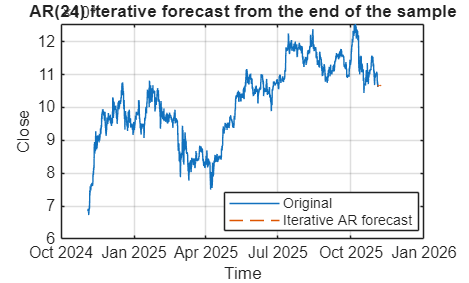


figure('Name','Hourly series with iterative AR forecast','Color','w');
plot(TTP.t, y, '-', 'DisplayName','Original'); hold on;
tForecast = TTP.t(end) + hours(1:K);
plot(tForecast, yForecast, '--', 'DisplayName','Iterative AR forecast');
grid on; box on;
xlabel('Time'); ylabel(valueCol);
legend('Location','best');
title(sprintf('AR(%d) iterative forecast from the end of the sample', noLags));